## SC simulation

**Created by: Yang Yang Lee

**Date: 29th Nov 2024

**Revision: 1.0

This code will simulate SNG generation and SC multiplication with AND gate.

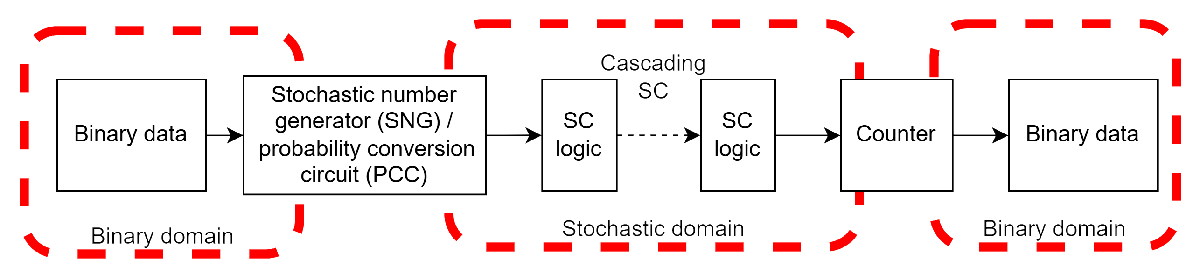

Before going to main code, define some functions.

function output = WBC(x)
    %this function is to convert LFSR or Sobol sequence into MUX select
    %input binary stream, the input is expected to have dimensions of
    %(runlength, resolution), e.g. (255,8)
    output = int8.empty(0,length(x));   %initialize array for speed
    for i = 1:length(x)                 %weighted binary converter to feed to MUX-based SNG
        output(i) = find(x(i,:),1)-1;   %return the position of the first non-zero element
    end
end
function output = MUXSNG(input, sel) 
    %this function is to generate bitstream from a binary input
    %sel is a stream of MUX select input wuth 255 clocks length
    %it could be LFSR sequence or Sobol sequence, passed through WBC
    bitstream = zeros([8,255],'logical');
    for i=1:8
        bitstream(i,:) = bitget(input,9-i)==1;
    end
    output = diag(bitstream(sel+1,:))';
end

Main code starts here:

1) generate random number sequence with linear feedback shift register (LFSR). This MATLAB simulation uses 8-bit resolution.

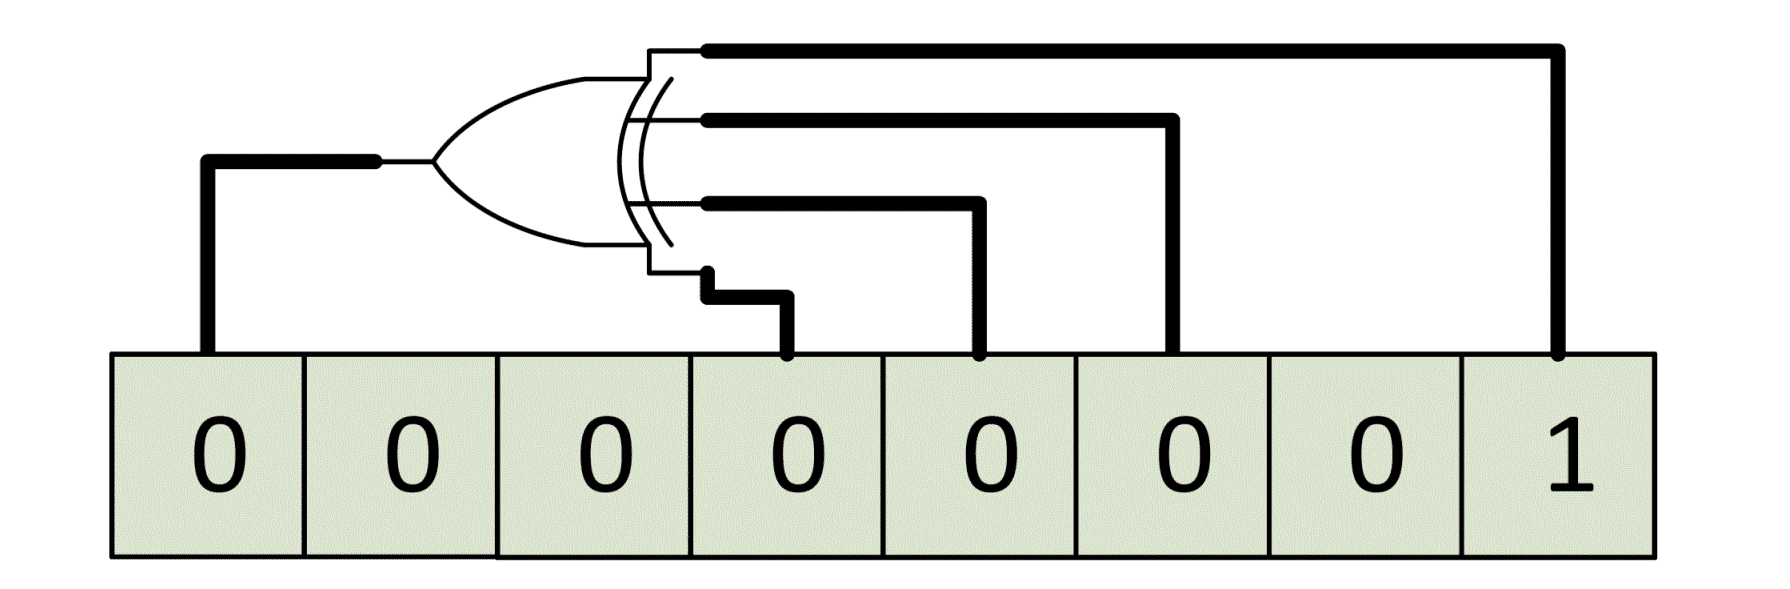

clear;
%setup LFSR
runlength = 255;
LFSR8 = [1 0 0 0 0 0 0 0];
for i = 1:runlength-1 %linear feedback shift register
    LFSR8(i+1,1) = xor(xor(LFSR8(i,8),LFSR8(i,6)),xor(LFSR8(i,5),LFSR8(i,4)));
    LFSR8(i+1,2) = LFSR8(i,1);    LFSR8(i+1,3) = LFSR8(i,2);    LFSR8(i+1,4) = LFSR8(i,3);
    LFSR8(i+1,5) = LFSR8(i,4);    LFSR8(i+1,6) = LFSR8(i,5);    LFSR8(i+1,7) = LFSR8(i,6);
    LFSR8(i+1,8) = LFSR8(i,7);
end
LFSR8a = flip(LFSR8,2); %permute the LFSR bit to generate lowest correlation random number
LFSR8sel = WBC(LFSR8);% input SNG sel (LFSR)
LFSR8sela = WBC(LFSR8a);% input SNG sel (LFSR)

Then, convert binary input into bitstreams with MUX SNG. Yes, MUX can be repurposed as SNG. Weighted binary generator (WBG, left image) is traditionally used but MUX is a more efficient approach for FPGA implementation.

Reference: [https://doi.org/10.1007/978-981-16-8129-5_94](https://doi.org/10.1007/978-981-16-8129-5_94)

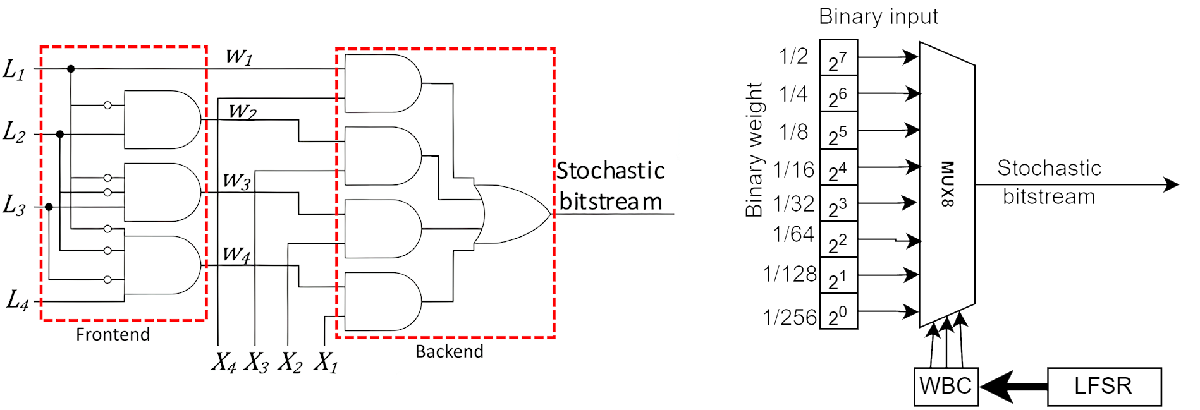

A = 128;% in fixed point, 128/255 = 0.5, can try any numbers
B = 102;% in fixed point, 102/255 = 0.4, can try any numbers
Abit = MUXSNG(A, LFSR8sel); % convert to bistream, dimensions of [1 255]
Bbit = MUXSNG(B, LFSR8sela);% convert to bistream, dimensions of [1 255]

Perform SC multiplication with AND gates

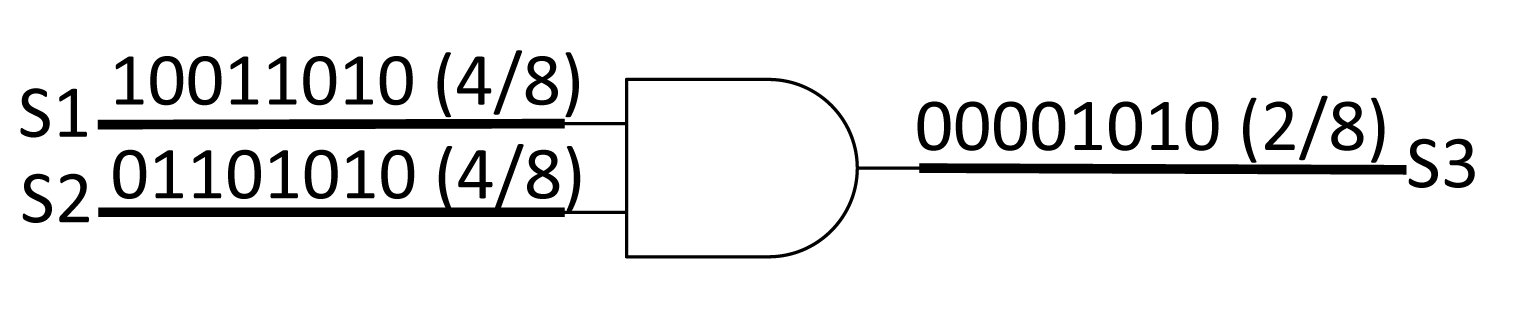

out = Abit & Bbit;%SC multiplication
% the output is a bitstream of 255 column, representing SC's 255 clock cycles.
%counter and recover floating point
sum(out,'all')/255

ans = 0.2000

%check binary computing
A/255 * B/255

ans = 0.2008